### **Signal Recording/Loading**

1) Sampling Rate = 8000 Hz

% % Audio Recording %%
% audio1 = audiorecorder(8000, 16, 1);
% disp('Start..');

Start..


% recordblocking(audio1, 5);
% disp('Stop..')

Stop..


% % Storing Audio %%
% x1=getaudiodata(audio1, "double");
% audiowrite("audio1.wav", x1, 8000);

[x1, Fs1]=audioread("audio1.wav"); % audio signal and sampling frequency (Hz)
d1=length(x1)/Fs1; % audio duration (seconds)
t1=0:1/Fs1:d1; % time series of signal (seconds)
t1=t1(1:end-1);
disp('Signal 1 (Fs=8000 Hz)')

Signal 1 (Fs=8000 Hz)


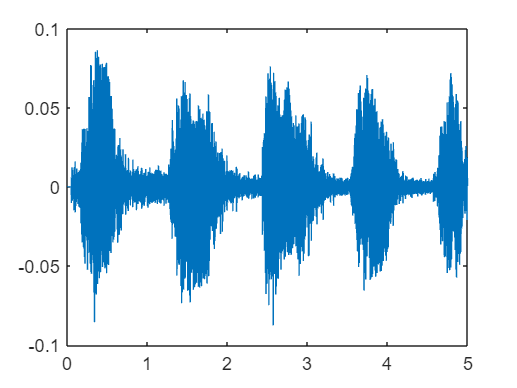

plot(t1,x1);

sound(x1,Fs1);

2) Sampling Rate = 1000 Hz

% audio2=audiorecorder(1000, 16, 1);
% disp('Start..');

Start..


% recordblocking(audio2, 5);
% disp('Stop..')

Stop..


% x2=getaudiodata(audio2, "double");
% audiowrite("audio2.wav", x2, 1000);

[x2,Fs2]=audioread("audio2.wav");
d2=length(x2)/Fs2;
t2=0:1/Fs2:d2;
t2=t2(1:end-1);
disp('Signal 2 (Fs=1000Hz)')

Signal 2 (Fs=1000Hz)


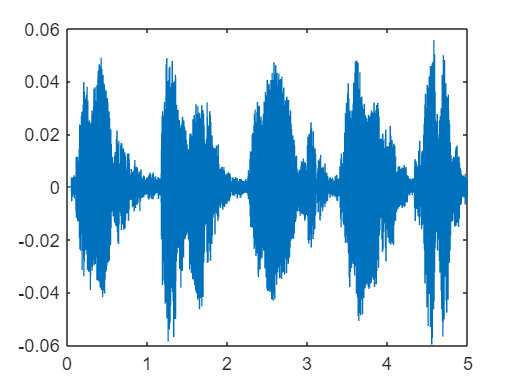

plot(t2,x2);

sound(x2,Fs2);

Speaker 2 (8000 Hz)

% audio1a = audiorecorder(8000, 16, 1);
% disp('Start..');

Start..


% recordblocking(audio1a, 5);
% disp('Stop..')

Stop..


% y1=getaudiodata(audio1a, "double");
% audiowrite("audio1a.wav", y1, 8000);

[y1, Fs3]=audioread("audio1a.wav"); % audio signal and sampling frequency (Hz)
d3=length(y1)/Fs3; % audio duration (seconds)
t3=0:1/Fs1:d3; % time series of signal (seconds)
t3=t3(1:end-1);
disp('Speaker 2 (Fs=8000 Hz)')

Speaker 2 (Fs=8000 Hz)


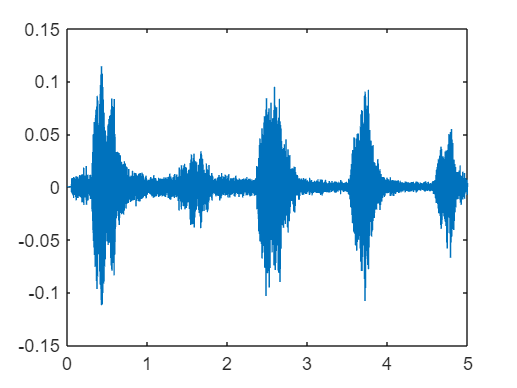

plot(t3,y1);

sound(y1,Fs3);

Speaker 2 (1000 Hz)

% audio2a = audiorecorder(1000, 16, 1);
% disp('Start..');

Start..


% recordblocking(audio2a, 5);
% disp('Stop..')

Stop..


% y2=getaudiodata(audio2a, "double");
% audiowrite("audio2a.wav", y2, 1000);

[y2, Fs4]=audioread("audio2a.wav"); % audio signal and sampling frequency (Hz)
d4=length(y2)/Fs4; % audio duration (seconds)
t4=0:1/Fs4:d4; % time series of signal (seconds)
t4=t4(1:end-1);
disp('Speaker 2 (Fs=1000 Hz)')

Speaker 2 (Fs=1000 Hz)


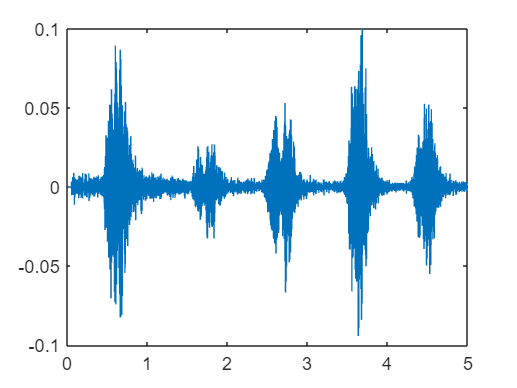

plot(t4,y2);

sound(y2,Fs4);

### **STFT**

wd = 60e-3; % window duration (seconds)
od = 10e-3; % overlap duration (seconds)

ws1 = floor(Fs1*wd); % window size in discrete domain
offset1 = ws1-floor(Fs1*od); % offset between start of consecutive windows
nw1 = ceil( (length(x1)-ws1) /offset1) + 1; % total number of windows in the signal

ws2 = floor(Fs2*wd);
offset2 = ws2-floor(Fs2*od);
nw2 = ceil( (length(x2)-ws2) /offset2) + 1;

Signal 1 (8000 Hz Sampling Rate)

s1f = sft(x1, Fs1, wd, od); % stft through function
f1f = -Fs1/2 : Fs1/ws1 : Fs1/2; % frequency series
f1f = f1f(2:end);
t1f = wd/2 : offset1/Fs1 : wd/2 + (nw1-1)*offset1/Fs1; % center time of each window
disp('STFT')

STFT


disp('Signal 1')

Signal 1


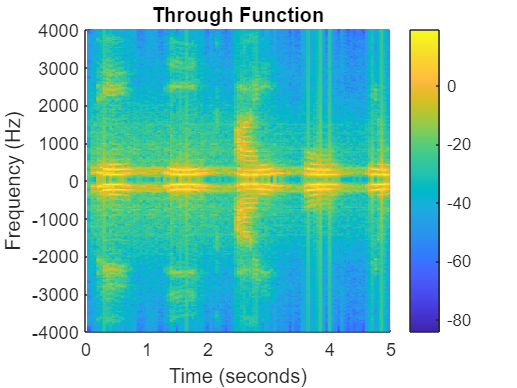

mesh(t1f, f1f, mag2db(s1f.') );
xlabel('Time (seconds)')
xlim([0 d1])
ylabel('Frequency (Hz)')
title('Through Function')
view(2)
colorbar

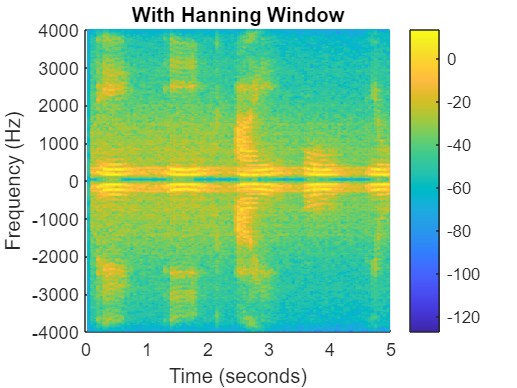

s1fh = sfth(x1, Fs1, wd, od); % appling hanning window
mesh(t1f, f1f, mag2db(s1fh.') );
xlabel('Time (seconds)')
xlim([0 d1])
ylabel('Frequency (Hz)')
title('With Hanning Window')
view(2)
colorbar

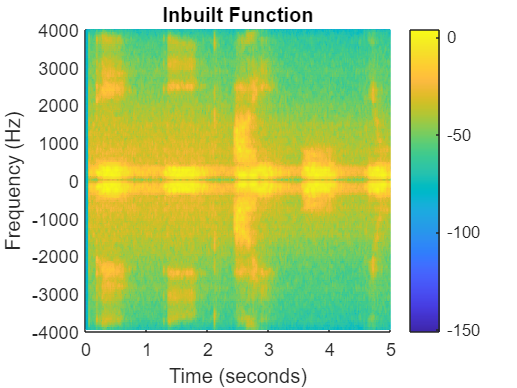

[s1, f1, t1a]=stft(x1, Fs1); % using inbuilt function
mesh(t1a, f1, mag2db( abs(s1) ) );
xlabel('Time (seconds)')
xlim([0 d1])
ylabel('Frequency (Hz)')
title('Inbuilt Function')
colorbar
view(2)

Signal 2 (1000 Hz Sampling Rate)

s2f=sft(x2, Fs2, wd, od);
f2f = -Fs2/2 : Fs2/ws2 : Fs2/2;
f2f = f2f(2:end);
t2f = wd/2 : offset2/Fs2 : wd/2 + (nw2-1)*offset2/Fs2;
disp('Signal 2')

Signal 2


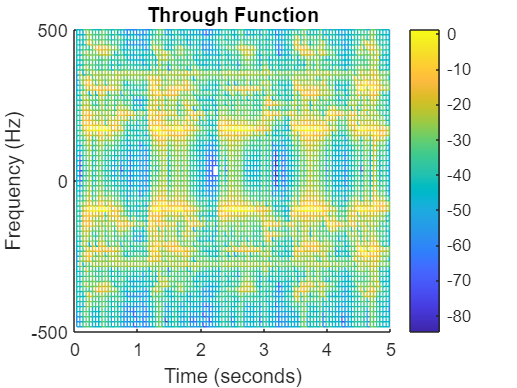

mesh(t2f, f2f, mag2db(s2f.') ); 
xlabel('Time (seconds)')
xlim([0 d2])
ylabel('Frequency (Hz)')
title('Through Function')
view(2)
colorbar

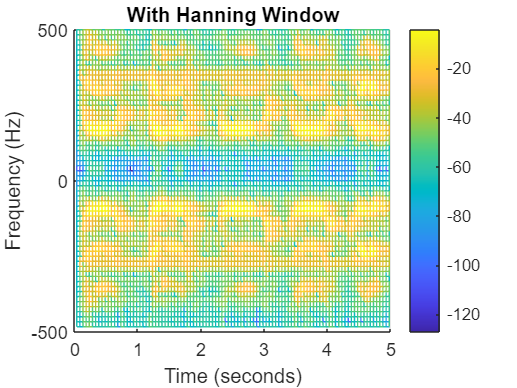

s2fh = sfth(x2, Fs2, wd, od); % appling hanning window
mesh(t2f, f2f, mag2db(s2fh.') );
xlabel('Time (seconds)')
xlim([0 d2])
ylabel('Frequency (Hz)')
title('With Hanning Window')
view(2)
colorbar

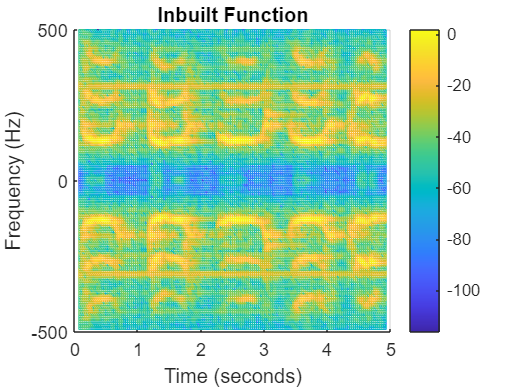

[s2, f2, t2a]=stft(x2, Fs2);
mesh(t2a, f2, mag2db( abs(s2) ) );
xlabel('Time (seconds)')
xlim([0 d2])
ylabel('Frequency (Hz)')
title('Inbuilt Function')
colorbar
view(2)

### **Linear Prediction Cofficients**

**Levison Durbin Algorithm**

Signal 1

p = 16; % number of prediction cofficient
lpc_lda1 = NaN(p, p, nw1); % cofficients from order 1 to p for all windows
error_lda1 = NaN(nw1, p+1); % signal energy (Epsilon(0)) and error of all orders from all windows
for i=1:nw1-1
    signal = x1((i-1)*offset1 + 1 : (i-1)*offset1 + ws1);
    [lpc_lda1(:,:,i), error_lda1(i,:)] = lda(signal, p);
end
signal = zeros(1, ws1); % padding zeros to last window
signal(1 : length(x1) - (nw1-1)*offset1 )=x1( (nw1-1)*offset1 + 1: end);
[lpc_lda1(:,:,nw1), error_lda1(nw1,:)] = lda(signal, p);

disp('Levison Durbin Algorithm')

Levison Durbin Algorithm


disp('Signal 1')

Signal 1


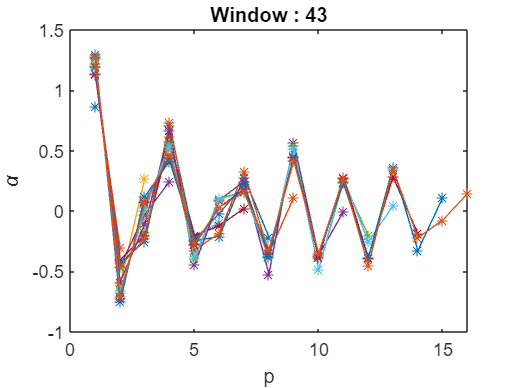


a = randi([1 nw1]); % randowly selecting a window number
plot(lpc_lda1(:,:,a)','*-') % plot all order cofficients of selected window
xlabel('p')
ylabel('\alpha')
title("Window : " + a)

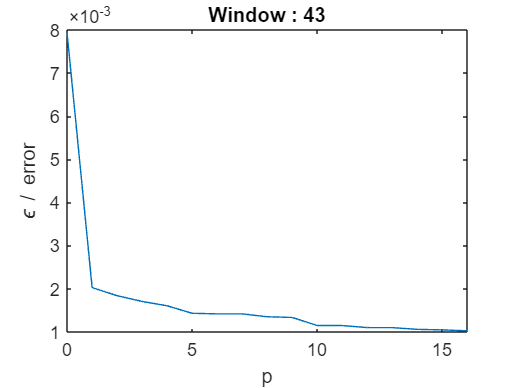


plot(0:p, error_lda1(a,:)) % ploting error of the window with p
xlabel('p')
xlim([0 p])
ylabel('\epsilon / error')
title("Window : " + a)

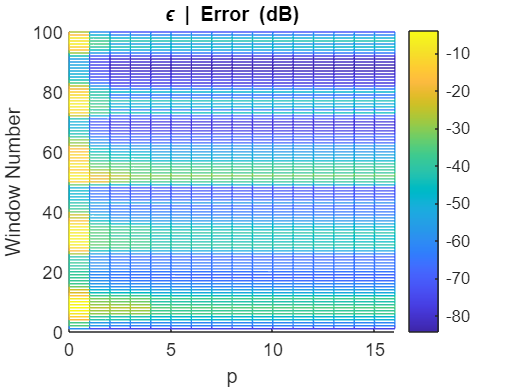

mesh(0:p, 1:nw1, mag2db(error_lda1))
xlabel('p')
xlim([0 p])
ylabel('Window Number')
title('\epsilon | Error (dB)')
view(2)
colorbar

Signal 2

lpc_lda2 = NaN(p, p, nw2);
error_lda2 = NaN(nw2, p+1);
for i=1:nw2-1
    signal = x2((i-1)*offset2 + 1 : (i-1)*offset2 + ws2);
    [lpc_lda2(:,:,i), error_lda2(i,:)] = lda(signal, p);
end
signal = zeros(1,ws2);
signal(1 : length(x2)-(nw2-1)*offset2) = x2((nw2-1)*offset2 + 1: end);
[lpc_lda1(:,:,nw2), error_lda1(nw2,:)] = lda(signal, p);

disp('Signal 2')

Signal 2


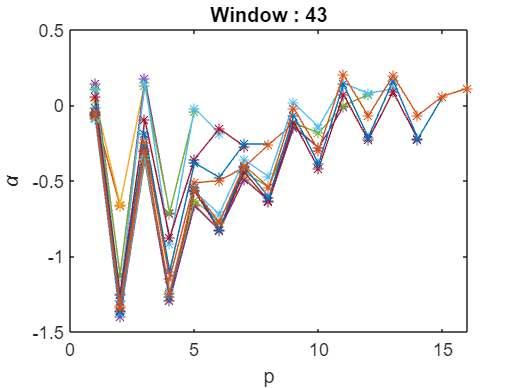


plot(lpc_lda2(:,:,a)','*-')
xlabel('p')
ylabel('\alpha')
title("Window : " + a)

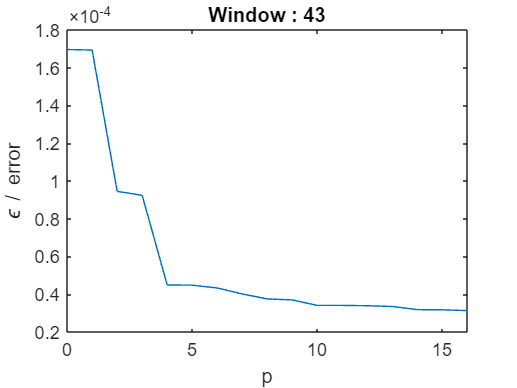


plot(0:p, error_lda2(a,:))
xlabel('p')
xlim([0 p])
ylabel('\epsilon / error')
title("Window : " + a)

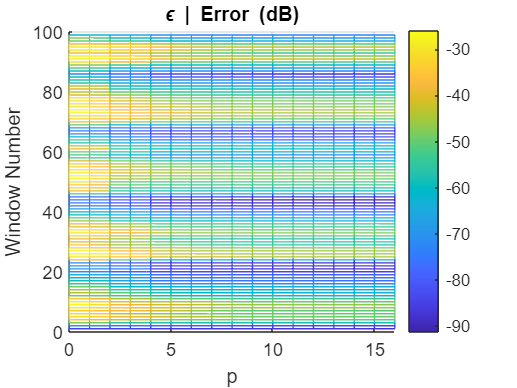

mesh(0:p, 1:nw2, mag2db(error_lda2))
xlabel('p')
xlim([0 p])
ylabel('Window Number')
title('\epsilon | Error (dB)')
view(2)
colorbar

#### Cholesky Decomposition Method

Signal 1

pa = [6 , 8, 12, 16]; % p values
% cofficients of all order for all windows
lpc_cdm1 = NaN(length(pa), max(pa), nw1);
% error of all order for all windows
error_cdm1 = NaN(nw1, length(pa));
for n=1:length(pa)
    pn = pa(n);
    signal = zeros(1, pn + ws1); % zero padding at beginning of first window to calculate covariance
    signal(pn+1:end) = x1(1:ws1);
    [lpc_cdm1(n, 1:pn, 1), error_cdm1(1, n)] = cdm(signal, pn);
    for i=2:nw1-1
        signal = x1((i-1)*offset1 - pn + 1 : (i-1)*offset1 + ws1);
        [lpc_cdm1(n, 1:pn, i), error_cdm1(i,n)]=cdm(signal, pn);
    end
    signal = zeros(1, pn + ws1); % zero padding at the end of last window
    signal(1 : length(x1) - (nw1-1)*offset1 + pn)=x1((nw1-1)*offset1 + 1 - pn : end);
    [lpc_cdm1(n, 1:pn, nw1), error_cdm1(nw1, n)]=cdm(signal, pn);
end

disp('Cholesky Decomposition Method')

Cholesky Decomposition Method


disp('Signal 1')

Signal 1


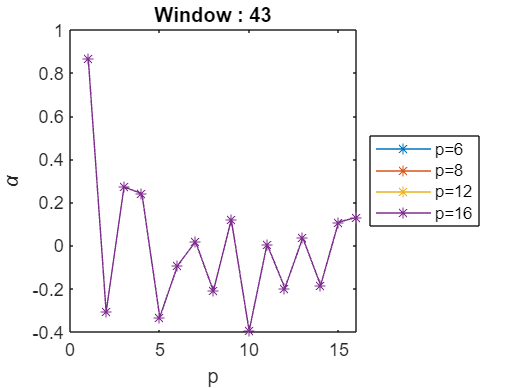


plot(lpc_cdm1(:,:,a)','*-')
xlabel('p')
ylabel('\alpha')
title("Window : " + a)
legend("p=6", "p=8", "p=12", "p=16",'Location','eastoutside')

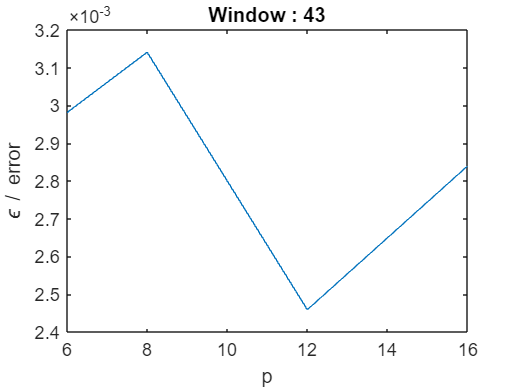


plot(pa, error_cdm1(a,:))
xlabel('p')
xlim([min(pa) max(pa)])
ylabel('\epsilon / error')
title("Window : " + a)

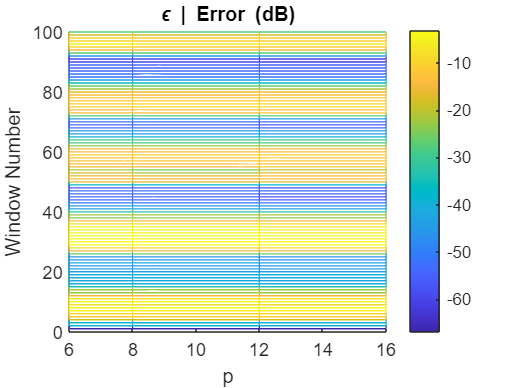

mesh(pa, 1:nw1, mag2db(error_cdm1))
xlabel('p')
xlim([min(pa) max(pa)])
ylabel('Window Number')
title('\epsilon | Error (dB)')
view(2)
colorbar

Signal 2

lpc_cdm2 = NaN(length(pa), max(pa), nw2);
error_cdm2=NaN(nw2, length(pa));
for n=1:length(pa)
    pn = pa(n);
    signal = zeros(1, pn + ws2);
    signal(pn+1 : end) = x2(1 : ws2);
    [lpc_cdm2(n, 1:pn, 1), error_cdm2(1, n)]=cdm(signal, pn);
    for i=2:nw2-1
        signal = x2((i-1)*offset2 - pn + 1 : (i-1)*offset2 + ws2);
        [lpc_cdm2(n, 1:pn, i), error_cdm2(i, n)] = cdm(signal, pn);
    end
    signal = zeros(1, pn + ws2);
    signal(1 : length(x2) - (nw2-1)*offset2 + pn) = x2((nw2-1)*offset2 + 1 - pn : end);
    [lpc_cdm2(n, 1:pn, nw2),error_cdm2(nw2, n)]=cdm(signal, pn);
end

disp('Signal 2')

Signal 2


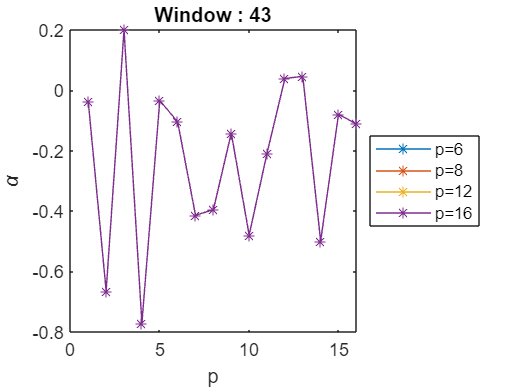


plot(lpc_cdm2(:,:,a)','*-')
xlabel('p')
ylabel('\alpha')
title("Window : " + a)
legend("p=6", "p=8", "p=12", "p=16",'Location','eastoutside')

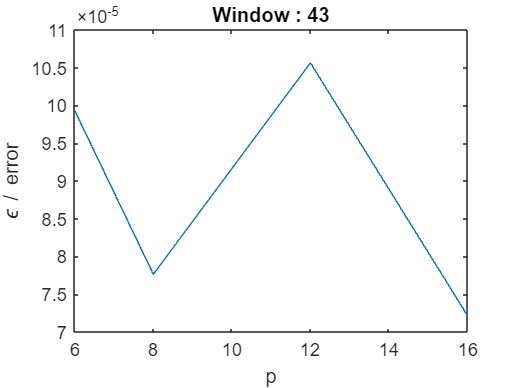


plot(pa, error_cdm2(a,:))
xlabel('p')
xlim([min(pa) max(pa)])
ylabel('\epsilon / error')
title("Window : " + a)

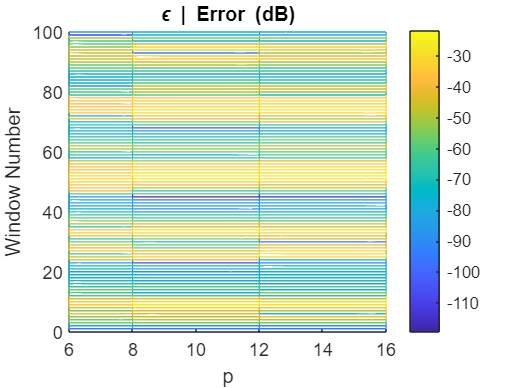

mesh(pa, 1:nw2, mag2db(abs(error_cdm2)))
xlabel('p')
xlim([min(pa) max(pa)])
ylabel('Window Number')
title('\epsilon | Error (dB)')
view(2)
colorbar

Comparison

disp('Comparassion of LDA and CDM cofficients of the same window')

Comparassion of LDA and CDM cofficients of the same window


disp('Signal 1')

Signal 1


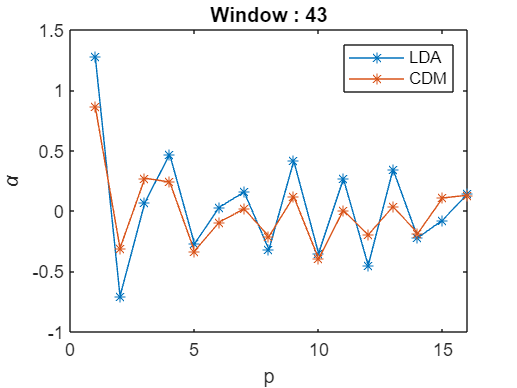


plot(lpc_lda1(16,:,a),'*-')
hold on
plot(lpc_cdm1(4,:,a),'*-')
hold off
xlabel('p')
ylabel('\alpha')
title("Window : " + a)
legend('LDA', 'CDM')

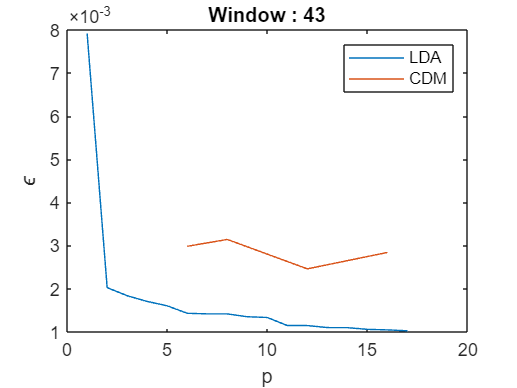

plot(error_lda1(a,:))
hold on
plot(pa, error_cdm1(a,:))
hold off
xlabel('p')
ylabel('\epsilon')
title("Window : " + a)
legend('LDA', 'CDM')

disp('Signal 2')

Signal 2


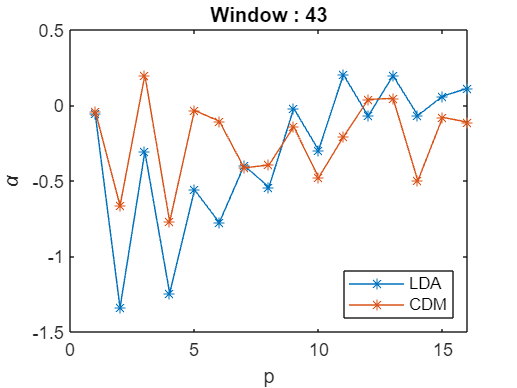


plot(lpc_lda2(16,:,a),'*-')
hold on
plot(lpc_cdm2(4,:,a),'*-')
hold off
xlabel('p')
ylabel('\alpha')
title("Window : " + a)
legend('LDA', 'CDM','location','southeast')

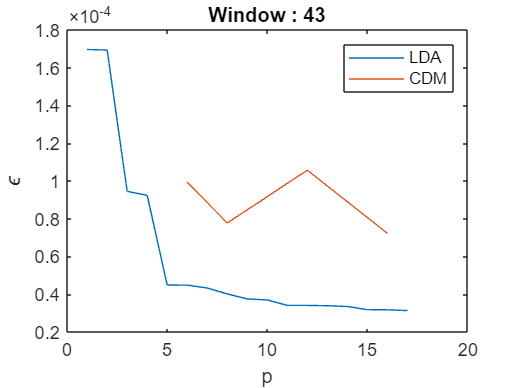

plot(error_lda2(a,:))
hold on
plot(pa, error_cdm2(a,:))
hold off
xlabel('p')
ylabel('\epsilon')
title("Window : " + a)
legend('LDA', 'CDM')

disp('Comparassion of Signal 1 and Signal 2 cofficients of the same window')

Comparassion of Signal 1 and Signal 2 cofficients of the same window


disp('LDA')

LDA


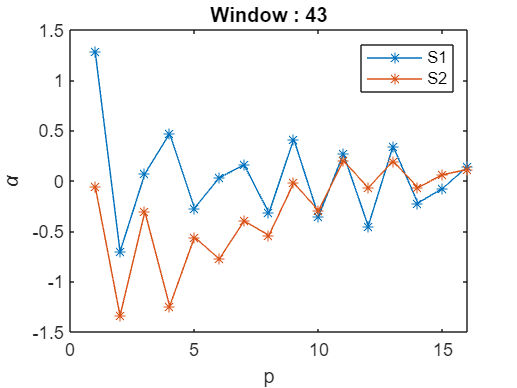


plot(lpc_lda1(16,:,a),'*-')
hold on
plot(lpc_lda2(16,:,a),'*-')
hold off
xlabel('p')
ylabel('\alpha')
title("Window : " + a)
legend('S1', 'S2')

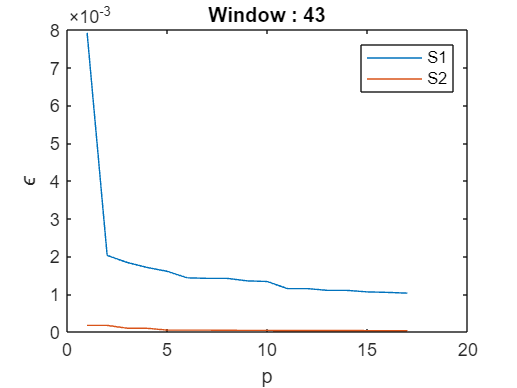

plot(error_lda1(a,:))
hold on
plot(error_lda2(a,:))
hold off
xlabel('p')
ylabel('\epsilon')
title("Window : " + a)
legend('S1', 'S2')

disp('CDM')

CDM


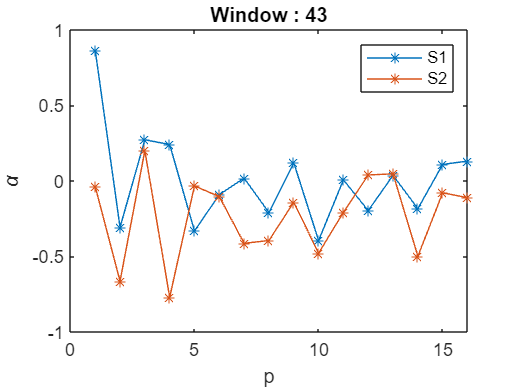


plot(lpc_cdm1(4,:,a),'*-')
hold on
plot(lpc_cdm2(4,:,a),'*-')
hold off
xlabel('p')
ylabel('\alpha')
title("Window : " + a)
legend('S1', 'S2')

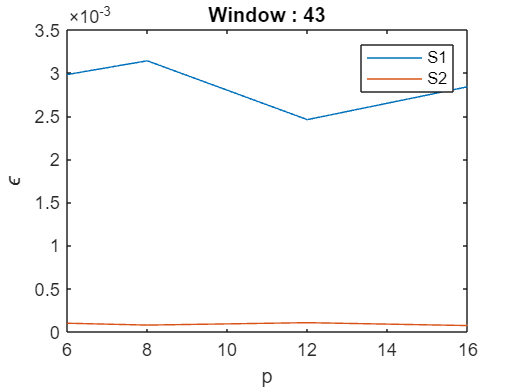

plot(pa, error_cdm1(a,:))
hold on
plot(pa, error_cdm2(a,:))
hold off
xlabel('p')
ylabel('\epsilon')
title("Window : " + a)
legend('S1', 'S2')

### **Quantization**

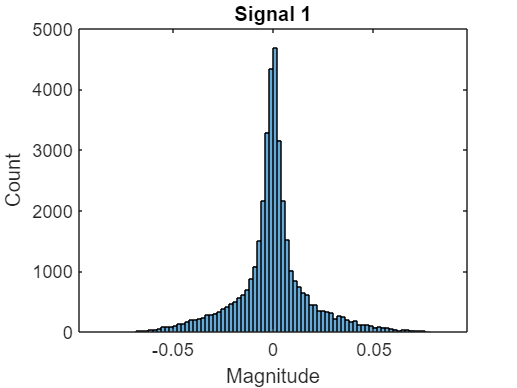

histogram(x1);
xlabel('Magnitude')
ylabel('Count')
title('Signal 1')

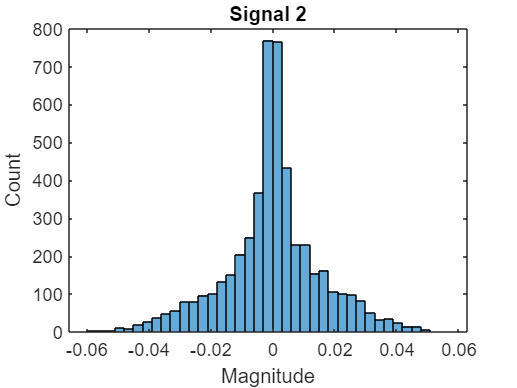

histogram(x2);
xlabel('Magnitude')
ylabel('Count')
title('Signal 2')

Signal 1

b=[3, 6, 8, 12, 16]; % quantization bits
uq1=NaN(length(b), length(x1)); % quantised signal
for k=1:5
    uq1(k,:) = uniform_quantise(x1, b(k));
end

disp('b bits uniform qunatisation')

b bits uniform qunatisation


disp('Signal 1')

Signal 1


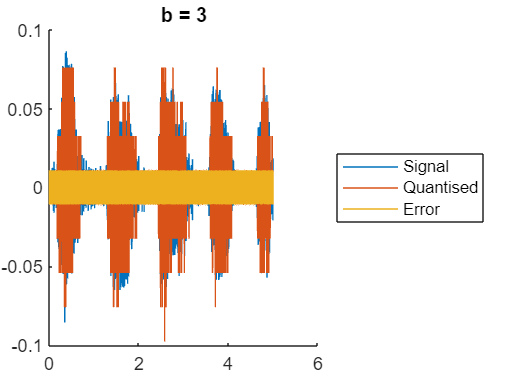

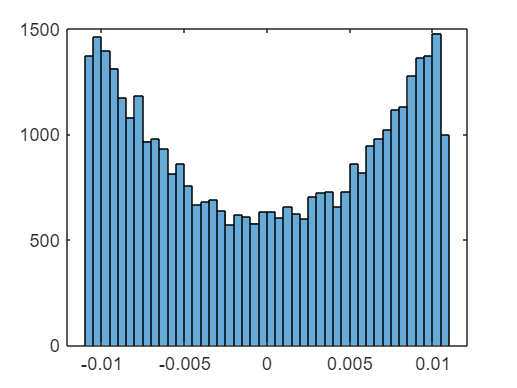

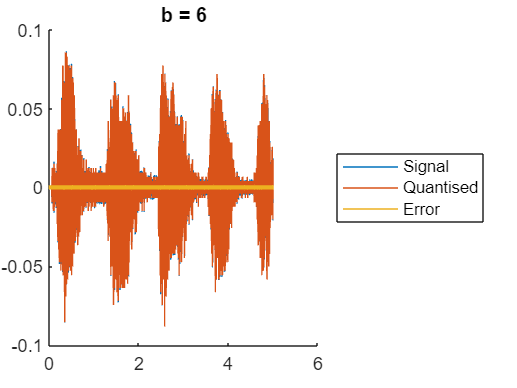

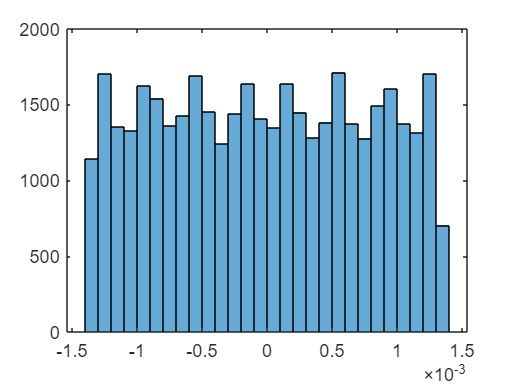

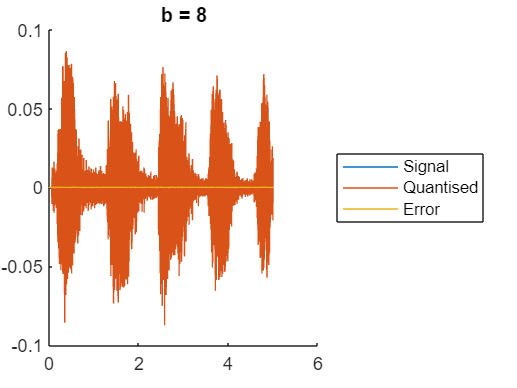

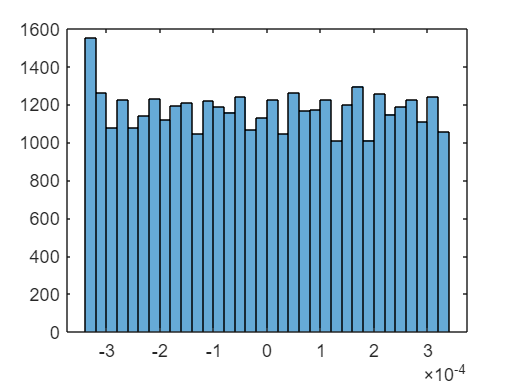

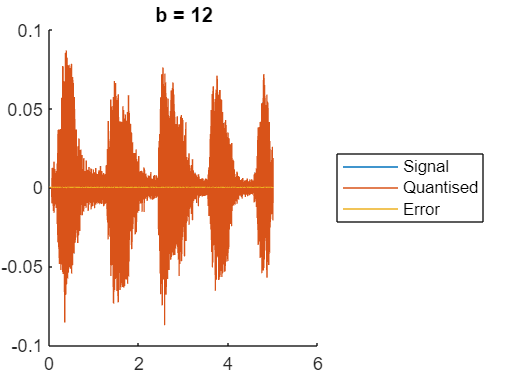

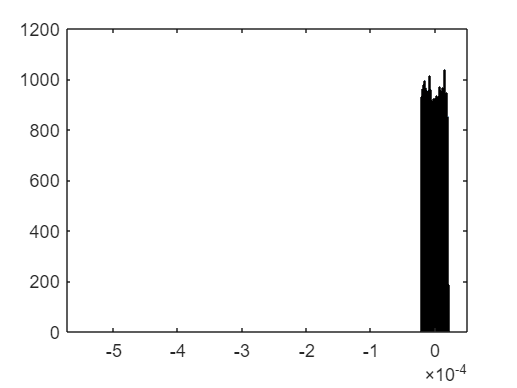


uqex1 = NaN(length(b), length(x1));
for n=1:5
    uqex1(n,:) = x1' - uq1(n,:);
    figure
    hold on
    plot(t1, x1);
    plot(t1, uq1(n,:))
    plot(t1, uqex1(n,:))
    title("b = " + b(n))
    hold off
    legend("Signal",'Quantised',"Error", 'location', 'eastoutside')
    figure
    histogram(uqex1(n,:))
end

Signal 2

uq2=NaN(length(b), length(x2));
for k=1:5
    uq2(k,:) = uniform_quantise(x2, b(k));
end

disp('Signal 2')

Signal 2


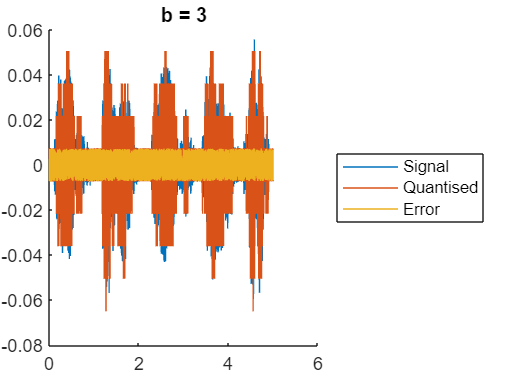

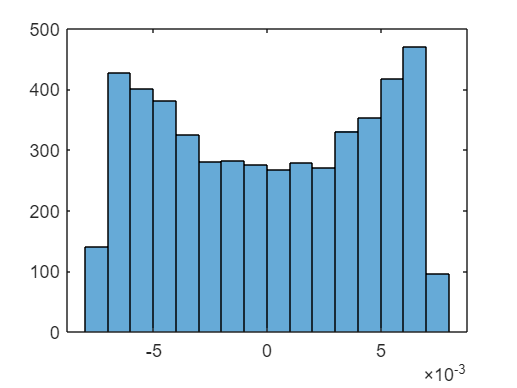

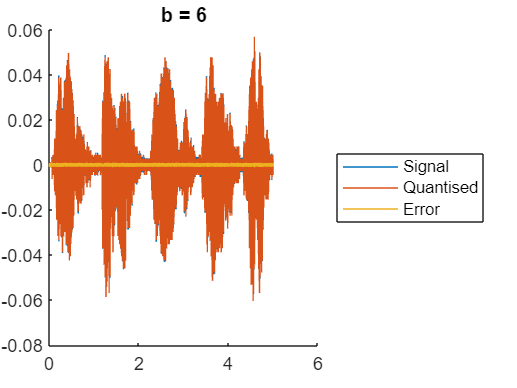

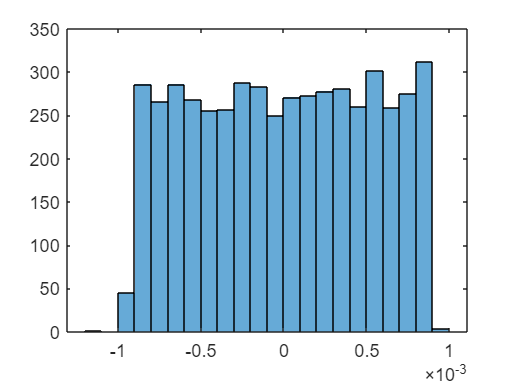

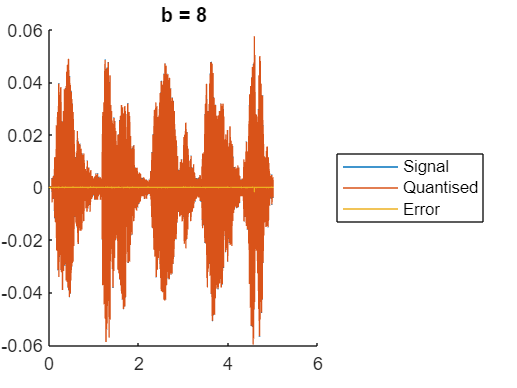

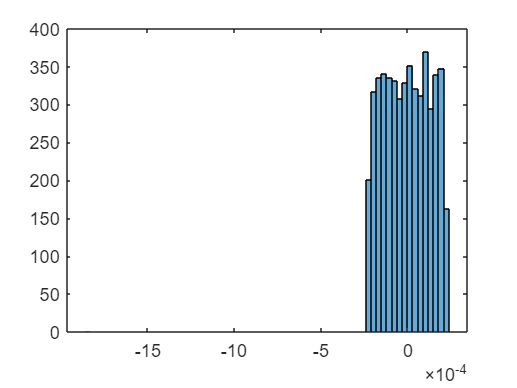

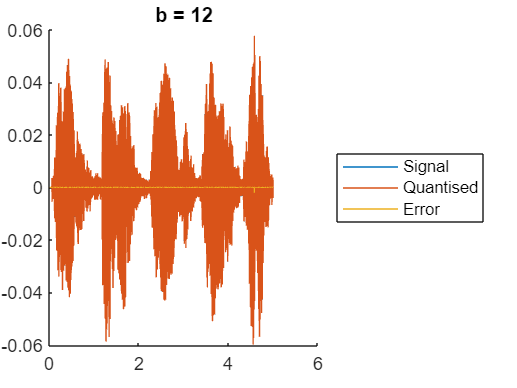

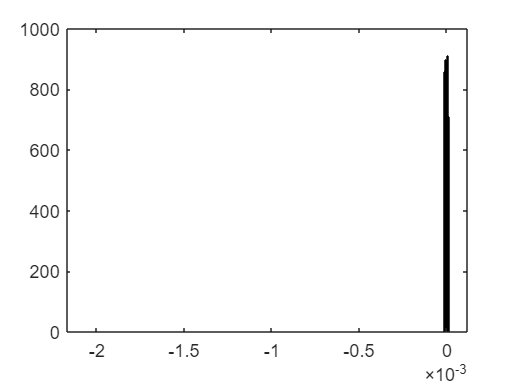


uqex2 = NaN(length(b), length(x2));

for n=1:5
    uqex2(n,:) = x2' - uq2(n,:);
    figure
    hold on
    plot(t2, x2);
    plot(t2, uq2(n,:))
    uqex2(n,:) = x2' - uq2(n,:);
    plot(t2, uqex2(n,:))
    title("b = " + b(n))
    hold off
    legend("Signal",'Quantised',"Error", 'location', 'eastoutside')
    figure
    histogram(uqex2(n,:))
end

### $\mu$- Law Compression

Signal 1

mu_law_x1 = mu_law_compression(x1, 60);

disp("μ-law Compression")

μ-law Compression


disp('Signal 1')

Signal 1


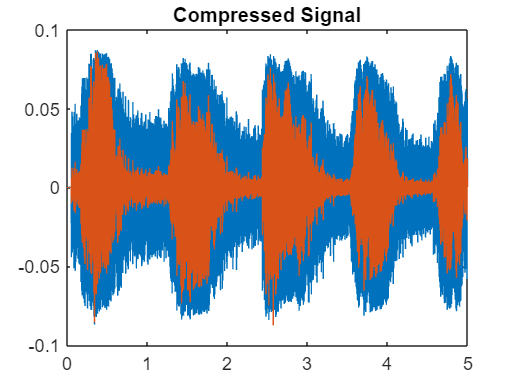

figure
plot(t1, mu_law_x1)
hold on
plot(t1, x1)
hold off
title('Compressed Signal')

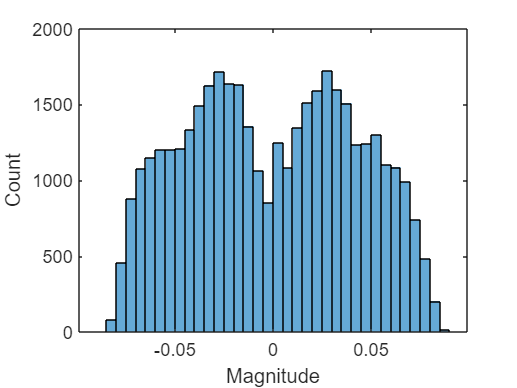

histogram(mu_law_x1)
xlabel('Magnitude')
ylabel('Count')

comqua1 = NaN(length(b), length(x1)); % quantization after compressing
for k=1:length(b)
    comqua1(k,:) = uniform_quantise(mu_law_x1, b(k));
end

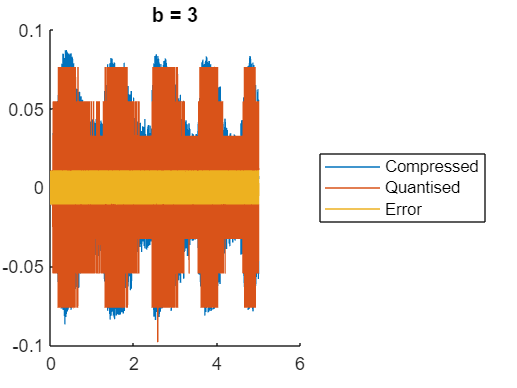

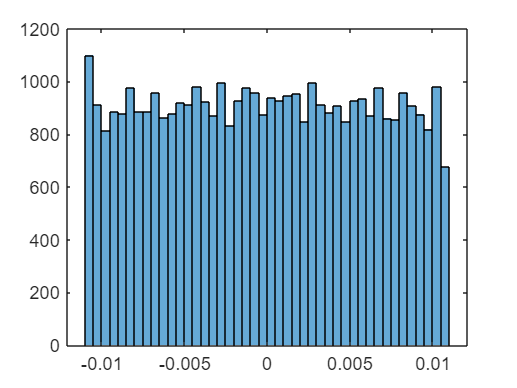

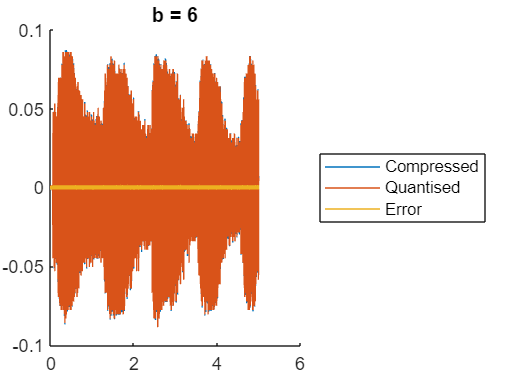

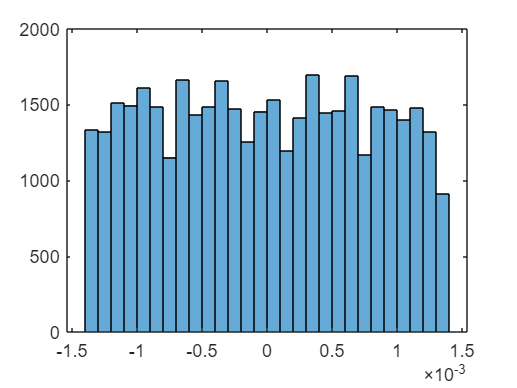

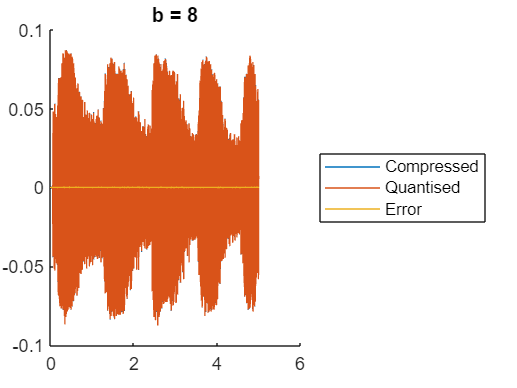

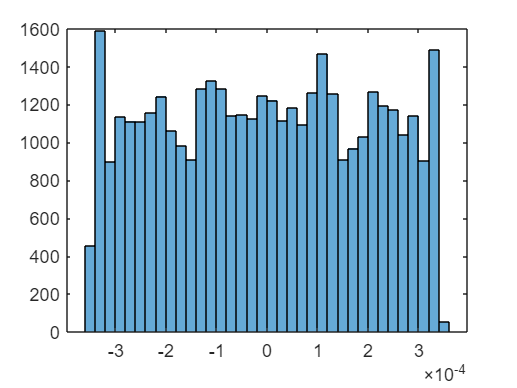

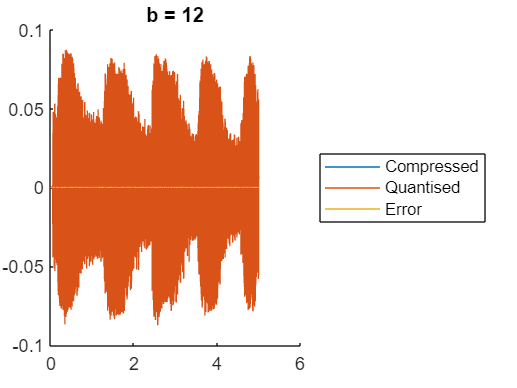

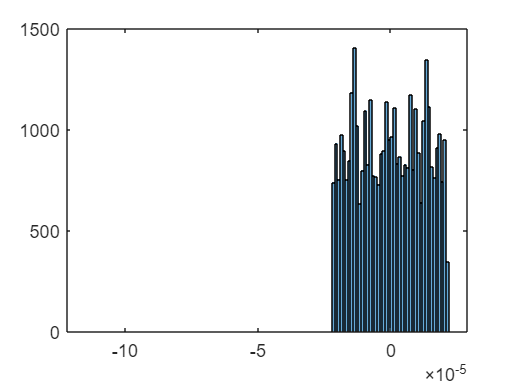

for n=1:5
    figure
    hold on
    plot(t1, mu_law_x1);
    plot(t1, comqua1(n,:))
    e = mu_law_x1' - comqua1(n,:);
    plot(t1, e)
    title("b = " + b(n))
    hold off
    legend("Compressed",'Quantised',"Error", 'location', 'eastoutside')
    figure
    histogram(e)
end

x1_re = NaN(length(b), length(x1));
for k=1:length(b)
    x1_re(k,:) = inverse_mu(comqua1(k,:), 60);
end

Signal 2

mu_law_x2 = mu_law_compression(x2, 40);

disp('Signal 2')

Signal 2


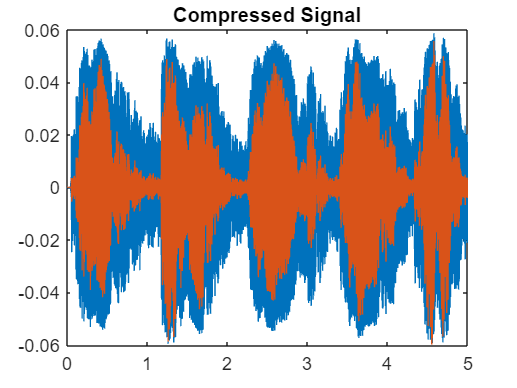


figure
plot(t2, mu_law_x2)
hold on
plot(t2, x2)
hold off
title('Compressed Signal')

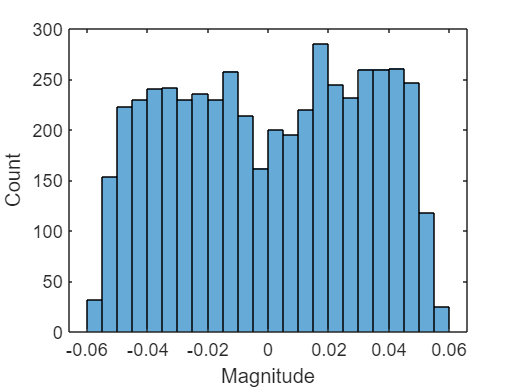

histogram(mu_law_x2)
xlabel('Magnitude')
ylabel('Count')

comqua2=NaN(length(b), length(x2));
for k=1:length(b)
    comqua2(k,:) = uniform_quantise(mu_law_x2, b(k));
end

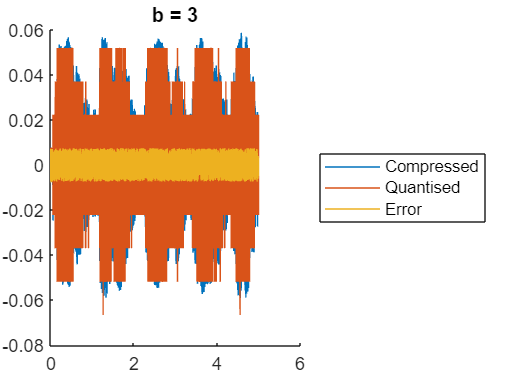

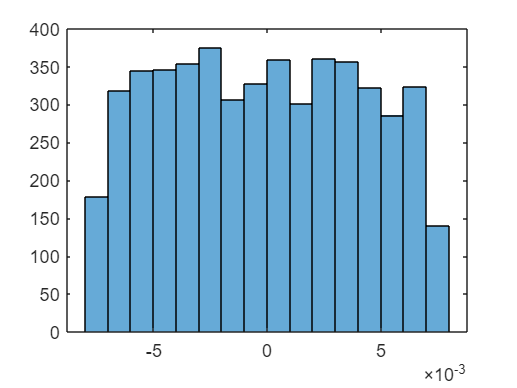

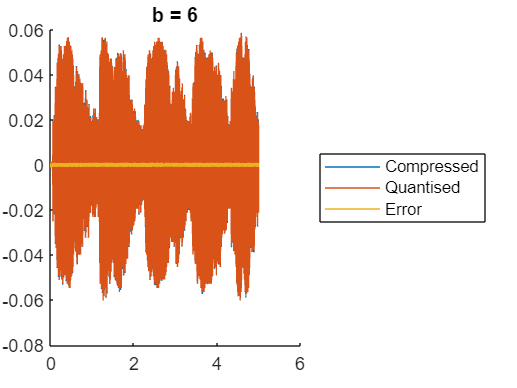

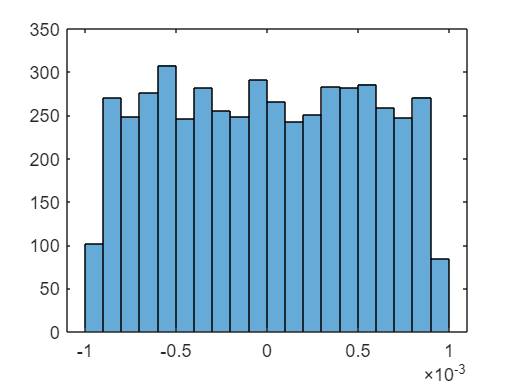

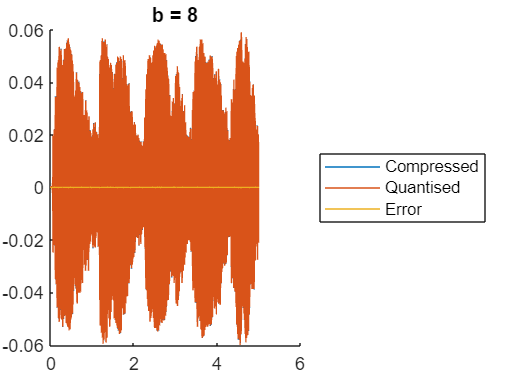

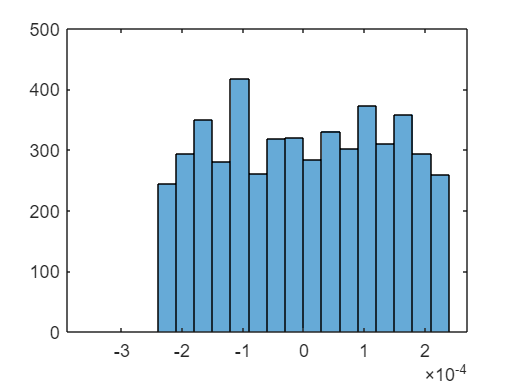

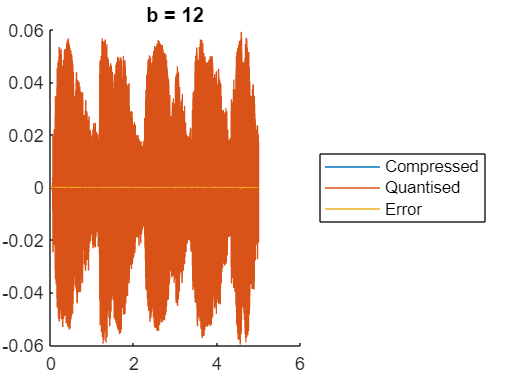

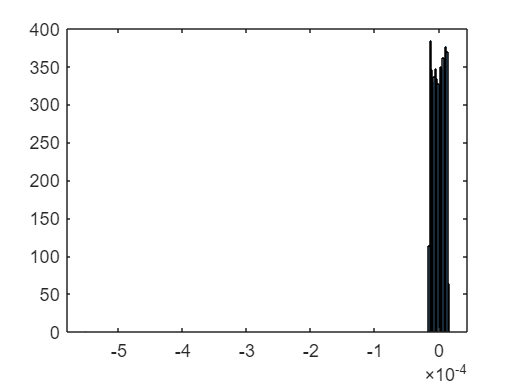

for n=1:5
    figure
    hold on
    plot(t2, mu_law_x2);
    plot(t2, comqua2(n,:))
    e = mu_law_x2' - comqua2(n,:);
    plot(t2, e)
    title("b = " + b(n))
    hold off
    legend("Compressed",'Quantised',"Error", 'location', 'eastoutside')
    figure
    histogram(e)
end

x2_re = NaN(length(b), length(x2)); % quantization after compressing
for k=1:length(b)
    x2_re(k,:) = inverse_mu(comqua2(k,:), 40);
end

RMS Error

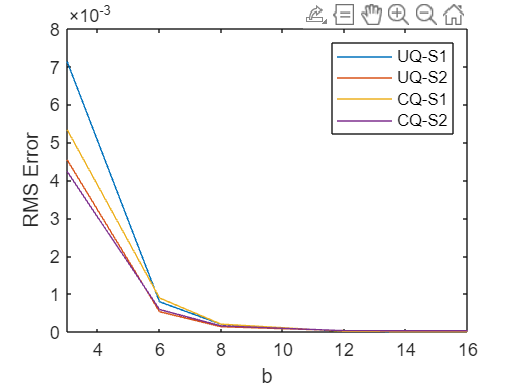

e_rms = NaN(5, 4);
e_rms(:,1) = rms(uqex1, 2);
e_rms(:,2) = rms(uqex2, 2);
e_rms(:,3) = rms(cqex1, 2);
e_rms(:,4) = rms(cqex2, 2);

plot(b,e_rms)
xlim([min(b) max(b)])
xlabel('b')
ylabel('RMS Error')
legend('UQ-S1','UQ-S2','CQ-S1','CQ-S2')

SNR

var_x1 = var(x1); % signal variance
snr_uq1 = NaN(1, length(b));
for n=1:length(b)
    snr_uq1(n) = mag2db( var_x1 / var(x1' - uq1(n,:)) ); % snr = variance(signal) / variance(q.e)
end

snr_mu1 = NaN(1,length(b));
cqex1 = NaN(length(b), length(x1));
for n=1:length(b)
    cqex1(n,:) = x1' - x1_re(n,:);
    snr_mu1(n) =  mag2db( var_x1 / var(cqex1(n,:)) );
end

var_x2 = var(x2);
snr_uq2=NaN(1,length(b));
for n=1:length(b)
    snr_uq2(n) = mag2db( var_x2 / var(x2'-uq2(n,:)) );
end

snr_mu2 = NaN(1,length(b));
cqex2 = NaN(length(b), length(x2));
for n=1:length(b)
    cqex2(n,:) = x2' - x2_re(n,:);
    snr_mu2(n) =  mag2db( var_x2 / var(cqex2(n,:)) );
end

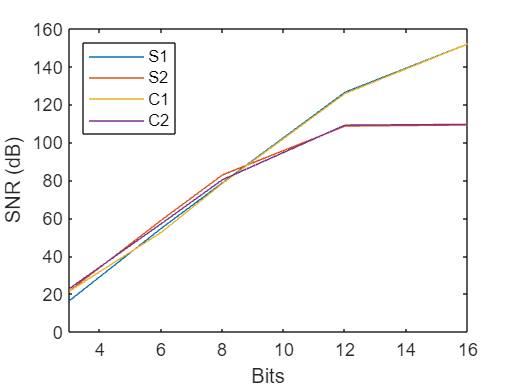

figure
plot(b, snr_uq1)
hold on
plot(b, snr_uq2)
plot(b, snr_mu1)
plot(b, snr_mu2)
hold off
xlabel('Bits')
xlim([min(b) max(b)])
ylabel('SNR (dB)')
legend('S1', 'S2', 'C1', 'C2', 'Location', 'northwest')

quantise_error = NaN(5, 4);


### **Mel-Frequency & MFCCs**

Signal 1

[mf1, df1] = mel_filters(Fs1, 22, ws1/2); % Mel-frequency filters
disp('Signal 1')

Signal 1


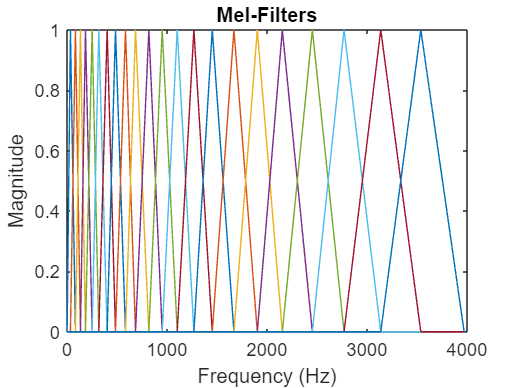

plot(0: Fs1/ws1: Fs1*(ws1-2)/2/ws1, mf1')
title('Mel-Filters')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

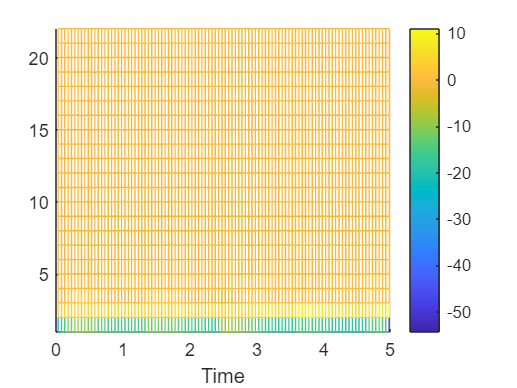

mfccx1 = mfccs(x1, Fs1, wd, od, 22); % MFCC
mesh(t1f, 1:22, mfccx1')
view(2)
xlabel('Time')
colorbar
xlim([0 5])
ylim([1 22])

Speaker 2

disp('Speaker 2')

Speaker 2


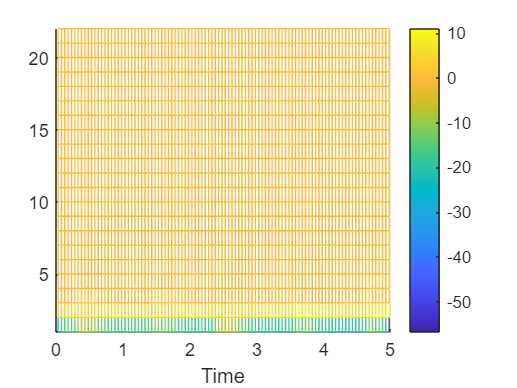

mfccy1 = mfccs(y1, Fs3, wd, od, 22); % MFCC
mesh(t1f, 1:22, mfccy1')
view(2)
xlabel('Time')
colorbar
xlim([0 5])
ylim([1 22])

disp('STFT and MFCC comparison after normalizig')

STFT and MFCC comparison after normalizig


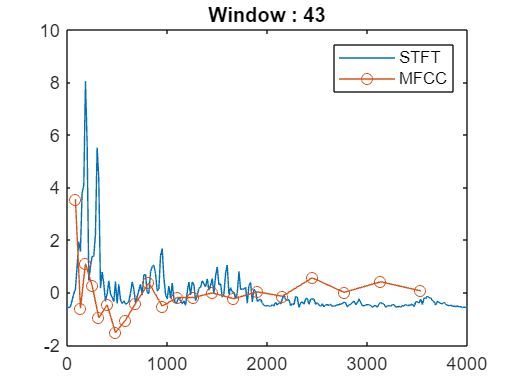


plot(0: Fs1/ws1: Fs1*(ws1-1)/ws1, normalize( abs( fft( x1((a-1)*offset1+1:(a-1)*offset1+ws1) .* hanning(ws1) ) ) ) );
hold on
plot(df1(3:23)./ws1*Fs1, normalize(mfccx1(a,2:end)),'o-');
hold off
xlim([0 Fs1/2])
title("Window : " + a)
legend('STFT', 'MFCC')

Signal 2

[mf2, df2] = mel_filters(Fs2, 20, ws2/2);
disp('Signal 2')

Signal 2


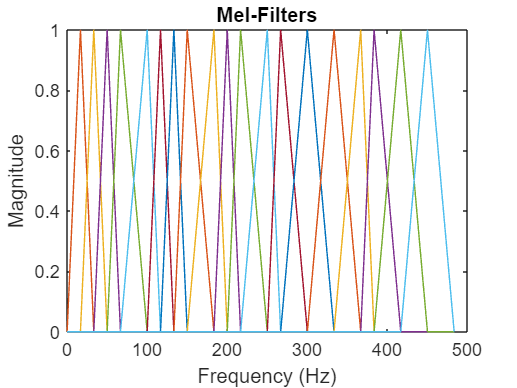

plot(0: Fs2/ws2: Fs2*(ws2-2)/2/ws2, mf2')
title('Mel-Filters')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

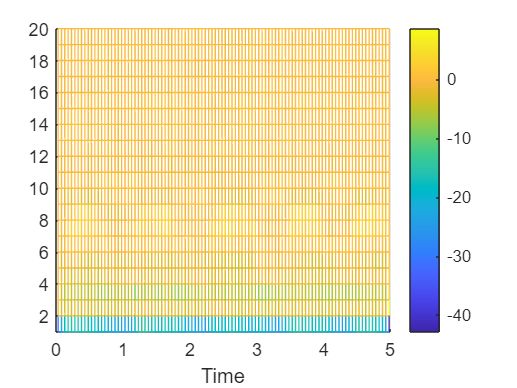

mfccx2 = mfccs(x2, Fs2, wd, od, 20);
mesh(t2f, 1:20, mfccx2')
view(2)
xlabel('Time')
colorbar
xlim([0 5])
ylim([1 20])

Speaker 2

disp('Speaker 2')

Speaker 2


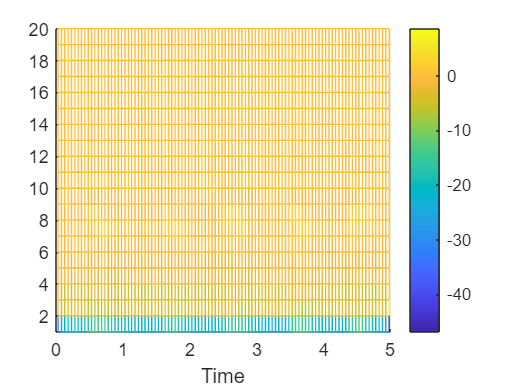

mfccy2 = mfccs(y2, Fs4, wd, od, 20);
mesh(t2f, 1:20, mfccy2')
view(2)
xlabel('Time')
colorbar
xlim([0 5])
ylim([1 20])

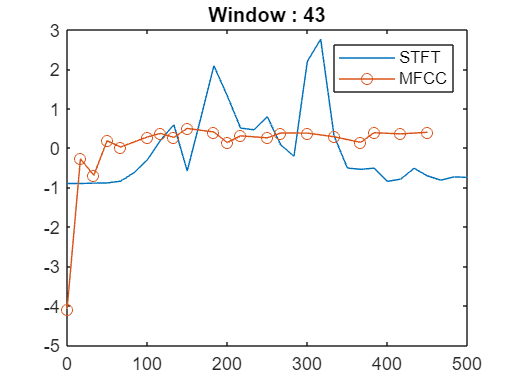

plot(0: Fs2/ws2: Fs2*(ws2-1)/ws2, normalize( abs( fft( x2((a-1)*offset2+1:(a-1)*offset2+ws2) .* hanning(ws2) ) ) ) );
hold on
plot(df2(2:21)./ws2*Fs2, normalize(mfccx2(a,1:end)),'o-');
hold off
xlim([0 Fs2/2])
title("Window : " + a)
legend('STFT', 'MFCC')

### Functions

STFT

function output = sft(x, Fs, wd, od)
    ws = Fs*wd; % window size in discrete
    os = Fs*od; % overlap size
    offset = ws-os; % offset between start of window
    windows = ceil( (length(x)-ws )/offset) + 1; % nuber of windows
    output = zeros(windows, ws);
    for i=1:windows-1
        signal = x((i-1)*offset + 1 : (i-1)*offset + ws); % windowed signal
        output(i,:) = abs(fft(signal)); % fft of window
    end
    signal = x((windows-1)*offset + 1:end);
    signal(length(x)-(windows-1)*offset + 1 : ws) = zeros(1, ws - length(x) + (windows-1)*offset); % zero padding of last window to complete window size
    output(windows,:) = abs(fft(signal));
    out = output(:, ceil(ws/2) : end);
    output(:, floor(ws/2)+2 : end) = output(:, 1 : ceil(ws/2)-1);
    output(:, 1 : floor(ws/2)+1) = out;
end

STFT with Hanning Window

function output = sfth(x, Fs, wd, od)
    ws = Fs*wd;
    os = Fs*od;
    offset = ws-os;
    windows = ceil( (length(x)-ws )/offset) + 1;
    output = zeros(windows, ws);
    window = hanning(ws);
    for i=1:windows-1
        signal = x((i-1)*offset + 1 : (i-1)*offset + ws);
        signal = signal .* window; % appling hanning window
        output(i,:) = abs(fft(signal));
    end
    signal = x((windows-1)*offset + 1:end);
    signal(length(x)-(windows-1)*offset + 1 : ws) = zeros(1, ws - length(x) + (windows-1)*offset);
    signal = signal.*window;
    output(windows,:) = abs(fft(signal));
    out = output(:, ceil(ws/2) : end);
    output(:, floor(ws/2)+2 : end) = output(:, 1 : ceil(ws/2)-1);
    output(:, 1 : floor(ws/2)+1) = out;
end

Levison Durbin Algorithm

function [alpha, epsilon] = lda(signal, p)
    alpha = NaN(p);
    correlation = zeros(1, p+1); % correlation matrix : R
    % R(i) = sum( s(m)*s(m-i) )
    for i=1:p+1
        for m=1:length(signal)-i+1
            correlation(i) = correlation(i) + signal(m)*signal(m+i-1);
        end
    end
    
    epsilon(1) = correlation(1); % E(0) = R(0)
    k = correlation(2) / epsilon(1); % k = R(1)/E(0)
    alpha(1, 1) = k; % alpha_1 (1st order) = k

    epsilon(2) = epsilon(1)*(1-k^2); % E(1) = E(0)*(1 - k^2)

    for i=2:p
        sum=0;
        for n=1:i-1
            sum = sum + alpha(i-1,n)*correlation(i-n+1);
        end
        k = (correlation(i+1) - sum)/epsilon(i); % k_i = ( R(i) - sum( alpha_j*R(i-j) ) )/E(i-1)
        alpha(i, i) = k; % alpha_i (ith order) = k_i
        % alpha_j (i order) = alpha_j (i-1 order) + k_i*alpha_i-j (i-1 order)
        for j=1:i-1
            alpha(i, j) = alpha(i-1, j) - k*alpha(i-1, i-j);
        end
        epsilon(i+1)=epsilon(i)*(1-k^2); % E(i) = E(i-1)*(1 - k_i^2)
    end
end

Cholesky Decomposition Method

function [alpha, error] = cdm(signal, p)
    phi = zeros(p+1); % covariance matrix
    % phi(i,j) = sum( s(m-i)*s(m-j) )
    for i=1:p+1
        for j=1:i
            for m=p+1:length(signal)
                phi(i,j) = phi(i,j) + signal(m-i+1)*signal(m-j+1);
            end
        end
    end
    
    d=zeros(1,p); % d matrix
    d(1)=phi(2,2); % d_1 = phi_11
    V=eye(p); % V matrix with diagonal 1
    % V_i,1 = phi_i1 / d_1
    for i=2:p
        V(i,1)=phi(i+1,2)/d(1);
    end
    for i=2:p-1
        % d_i = phi_ii - sum( V_ik^2 * d_k )
        d(i)=phi(i+1,i+1); 
        for k=1:i-1
            d(i) = d(i) - V(i,k)^2*d(k);
        end
        % V_ki = (phi_ki - sum( V_kj * d_j * V_ji) )/d_i
        for k=i+1:p
            V(k,i)=phi(k+1,i+1);
            for j=1:k-1
                V(k,i)=V(k,i)-V(k,j)*d(j)*V(i,j);
            end
            V(k,i) = V(k,i)/d(i);
        end
    end
    d(p)=phi(p+1,p+1);
    for i=1:p-1
        d(p)=d(p)-V(p,i)^2*d(i);
    end
    
    Y=zeros(1,p); % Y matrix
    % Y = shi_i - sum( V_ij * Y_j )
    Y(1)=phi(2,1);
    for i=2:p
        Y(i)=phi(i+1,1);
        for j=1:i-1
            Y(i)=Y(i)-V(i,j)*Y(j);
        end
    end
    
    alpha=zeros(1,p);
    % alpha_i = Y_i / d_i - sum( V_ij * alpha_j )
    alpha(p)=Y(p)/d(p);
    for i=p-1:-1:1
        alpha(i)=Y(i)/d(i);
        for j=i+1:p
            alpha(i)=alpha(i)-V(i,j)*alpha(j);
        end
    end

    error=phi(1,1); % error = phi_00 - sum( alpha_i * phi_i0 )
    for i=1:p
        error=error-alpha(i)*phi(i+1,1);
    end
end

Uniform Quantization

function out = uniform_quantise(signal, b)
    m = max(signal); % maximum signal value
    delta = (m - min(signal) )/(2^b); % partition size
    out = NaN(1, length(signal));
    for i=1:length(signal)
        if(signal(i) == m)
            out(i) = (2^(b-1) - 0.5)*delta;
        else
            out(i) = (floor(signal(i)/delta)+0.5)*delta;
        end
    end
end

$\mu$- Law Compression

function out = mu_law_compression(signal,mu)
    xm = max(abs(signal));
    out = xm * log10(1 + mu*abs(signal)/xm)/log10(1 + mu) .* sign(signal);
end

function out = inverse_mu(signal, mu)
    xm = max(abs(signal));
    out = xm/mu * ((1 + mu).^(abs(signal)/xm) - 1) .* sign(signal);
end

Mel-Frequency Filters

function [out, df] = mel_filters(fm, nf, n)
    out = zeros(nf, n);
    mel_fm = 1125*log(1 + fm/700); % mel frequency of highest frequency
    mfp = 0: mel_fm/(nf+1) : mel_fm; % mel frequency partitions
    fp = 700*(exp(mfp./1125)-1); % original frequency partitions
    df = floor(fp./fm*n); % discrete indices of frequency peaks
    df(end) = df(end)-1;
    for i=1:nf
        % rising slope equation
        for j=df(i):df(i+1)
            out(i, j+1) = (j - df(i)) / (df(i+1) - df(i));
        end
        % falling slope equation
        for j=df(i+1)+1:df(i+2)
            out(i, j+1) = 1 + (df(i+1) - j) / (df(i+2) - df(i+1));
        end
    end
end

MFCC

function out = mfccs(x, Fs, wd, od, nf)
    ws = Fs*wd; % window size
    os = Fs*od; % overlap size
    offset = ws-os; % offset between start of two consecutive windows
    windows = ceil( (length(x)-ws) / offset ) + 1; % number of windows
    [mf, df] = mel_filters(Fs/2, nf, ceil(ws/2)); % mel-frequency filters (V_r)
    a = zeros(1, nf); % A_r = sum (V_r(k) ^ 2)
    out = zeros(windows, nf);
    hw = hanning(ws);
    for n=1:nf
        for k = df(n)+2:df(n+2)
            a(n) = a(n) + mf(n,k)^2;
        end
    end
    for i=1:windows-1
        signal = x((i-1)*offset + 1:(i-1)*offset + ws); % windowed signal
        signal = signal .* hw;
        dftx = abs(fft(signal)); % dft of windowed signal
        mfr = zeros(1, nf); % MF(r) = sum( (V_r(k) * DFT(k)) ^ 2 ) / A_r
        for r=1:nf
            mfr(r) = sum( ( mf(r,:)' .* dftx(1:ws/2) ).^2 );
            mfr(r) = mfr(r)/a(r);
        end
        mfr = log10(mfr);
        out(i,:) = dct(mfr);
    end
    signal = zeros(1, ws);
    signal(1 : length(x)-(windows-1)*offset) = x((windows-1)*offset + 1 : end);
    signal = signal .* hw;
    dftx = abs(fft(signal));
    mfr = zeros(1, nf);
    for r=1:nf
        mfr(r) = sum( ( mf(r,:) .* dftx(1:ws/2) ).^2 );
        mfr(r) = mfr(r)/a(r);
    end
    mfr = log10(mfr);
    out(windows,:) = dct(mfr);
end